% Setup the workspace
% (Run once)

% this has a library to generate density scatterers (from Rehman)
addpath /data/tbrevett/Projects/DistributedAberrationCorrection/kWaveSoundSpeedSim4Thurston/standard_lib/

% this is a version of fullwave with associated functions (from Leah)
addpath /data/tbrevett/Programs/fullwave/fun/ % helper functions
copyfile /data/tbrevett/Programs/fullwave/bin/fullwave2_executable bin/ % executable

% kWave and kWaveArray should be added here


%#ok<*UNRCH> ignore unreachable code due to constant values
%#ok<*BDLGI> ignore casting numbers to logical values
device = -logical(gpuDeviceCount); % select 0 for cpu, -1 for gpu if you have one
% setup;  % add all the necessary paths
% setup parallel; % start a parpool for faster CPU processing
parpool('threads'); % start a limited but faster parpool - valid for R2021a+
setup CUDA cache;  % setup CUDA paths & recompile and cache local mex/CUDA binaries

% Setup the workspace
% (Run once)

% this has a library to generate density scatterers (from Rehman)
addpath /data/tbrevett/Projects/DistributedAberrationCorrection/kWaveSoundSpeedSim4Thurston/standard_lib/

% this is a version of fullwave with associated functions (from Leah)
addpath /data/tbrevett/Programs/fullwave/fun/ % helper functionsjob = createJob(clu);
copyfile /data/tbrevett/Programs/fullwave/bin/fullwave2_executable bin/ % executable

% my version of kWave and kWaveArray - may have modifications 
addpath /data/tbrevett/Programs/MATLAB/k-Wave/
addpath /data/tbrevett/Programs/MATLAB/k-WaveArray/;


%#ok<*UNRCH> ignore unreachable code due to constant values
%#ok<*BDLGI> ignore casting numbers to logical values
device = -logical(gpuDeviceCount); % select 0 for cpu, -1 for gpu if you have one
% setup;  % add all the necessary paths
% setup parallel; % start a parpool for faster CPU processingqups
% if isempty(gcp()), parpool('threads'); end % start a limited but faster parpool - valid for R2021a+
% setup CUDA cache;  % setup CUDA paths & recompile and cache local mex/CUDA binaries
parpool('threads'); % start a limited but faster parpool - valid for R2021a+

Error using parpool
Found an interactive session. You cannot have multiple interactive sessions open simultaneously. To terminate the existing session,
use delete(gcp('nocreate')).

setup CUDA cache;  % setup CUDA paths & recompile and cache local mex/CUDA binaries

%run /data/smunot/matlab/qups/setup.m

## Setup pt1

xdc = TransducerArray.L12_5V(); % linear array
xdc.numel = 256;


 lambda = 1500/xdc.fc;
 tscan = ScanCartesian('x', [-30e-3:lambda/4:30e-3],'z',[0:lambda/8:80e-3]);

% Choose an imaging region
scan = tscan; % use the same as the simulation region

c0 = 1500;
rho0 =1020;


switch "ITIS"

    case 'MIDA'
        load MIDA_crho_slice.mat
        numx = size(mida_rho_slice,2);
        numz = size(mida_rho_slice,1);
        PieceScan = ScanCartesian('xb', [-30e-3 30e-3], 'zb', [0 80e-3], 'nx', numx, 'nz', numz);
        med = Medium.Sampled(PieceScan,mida_c_slice, mida_rho_slice);
        [cc, pp] = props(med,tscan,["c", "rho"]);
        med2 = Medium.Sampled(tscan, cc, pp)

    case 'ITIS'
        load ITIS_crho_slice.mat
        numx = size(itis_rho_slice,2);
        numz = size(itis_rho_slice,1);
        PieceScan = ScanCartesian('xb', [-30e-3 30e-3], 'zb', [0 80e-3], 'nx', numx, 'nz', numz);
        med = Medium.Sampled(PieceScan,itis_c_slice, itis_rho_slice);
        [cc, pp] = props(med,tscan,["c", "rho"]);
        med2 = Medium.Sampled(tscan, cc, pp)
end

med2 =   Medium with properties:

         c0: 1540
       rho0: 1020
       BoA0: NaN
     alpha0: NaN
    alphap0: 1.0100
    pertreg: {@(p)dealret(p,cfun,rfun,bfun,afun,apfun)}




%s_rad = 5*lambda/21;
%%ifun = @(p) vecnorm(p - [0;0;50e-3],2,1) < s_rad; % selection function: true if within the perturbation region
%preg_scat = {ifun, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

%pertreg = med2.pertreg;
%med2.pertreg = [pertreg,{preg_scat}];

    

## Construct a medium

%opts_med = ["scatterer", "four_regions", "array", "diffuse"]; % medium options
%switch opts_med(2)
pertreg = med2.pertreg;
s_rad = 5*lambda/21;

switch "horz_array_double"

    case 'scatterer'
        % Create a Medium with just a Point Scatterer

        ifun = @(p) vecnorm(p - [0;0;40e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat = {ifun, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties
        med2.pertreg = [pertreg,{preg_scat}];


    case 'horz_array'

        ifun = @(p) vecnorm(p - [0;0;25e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat = {ifun, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun2 = @(p) vecnorm(p - [0.004;0;25e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat2 = {ifun2, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun3 = @(p) vecnorm(p - [-0.008;0;25e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat3 = {ifun3, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun4 = @(p) vecnorm(p - [0.008;0;25e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat4 = {ifun4, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun5 = @(p) vecnorm(p - [-0.004;0;25e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat5 = {ifun5, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties
        med2.pertreg = [pertreg,  {preg_scat},{preg_scat2},{preg_scat3},{preg_scat4},{preg_scat5}]
        %med = Medium('c0', c0, 'rho0', rho0, 'pertreg', [preg_layered, {preg_scat},{preg_scat2},{preg_scat3},{preg_scat4},{preg_scat5}]);
    case 'horz_array_double'

        ifun = @(p) vecnorm(p - [0;0;35e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat = {ifun, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun2 = @(p) vecnorm(p - [0.004;0;35e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat2 = {ifun2, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun3 = @(p) vecnorm(p - [-0.008;0;35e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat3 = {ifun3, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun4 = @(p) vecnorm(p - [0.008;0;35e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat4 = {ifun4, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun5 = @(p) vecnorm(p - [-0.004;0;35e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat5 = {ifun5, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

         ifun6 = @(p) vecnorm(p - [0;0;50e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat6 = {ifun6, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun7 = @(p) vecnorm(p - [0.004;0;50e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat7 = {ifun7, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun8 = @(p) vecnorm(p - [-0.008;0;50e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat8 = {ifun8, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun9 = @(p) vecnorm(p - [0.008;0;50e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat9 = {ifun9, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun10 = @(p) vecnorm(p - [-0.004;0;50e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat10 = {ifun10, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        med2.pertreg = [pertreg, {preg_scat},{preg_scat2},{preg_scat3},{preg_scat4},{preg_scat5},{preg_scat6},{preg_scat7},{preg_scat8},{preg_scat9},{preg_scat10}];
    case 'vert_array'
        % add a point scatterer
        % s_rad = max([tscan.dx, tscan.dz]); %, 260e-6); % scatterer radius
        %ifun = @(p) vecnorm(p - [0;0;30e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        %preg_scat = {ifun, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties
        s_rad = 2*lambda/21; %, 260e-6); % scatterer radius
        ifun = @(p) vecnorm(p - [0;0;30e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat = {ifun, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun2 = @(p) vecnorm(p - [0;0;20e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat2 = {ifun2, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun3 = @(p) vecnorm(p - [0;0;25e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat3 = {ifun3, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun4 = @(p) vecnorm(p - [0;0;35e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat4 = {ifun4, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        ifun5 = @(p) vecnorm(p - [0;0;40e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat5 = {ifun5, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        % construct the medium
        % med = Medium('c0', c0, 'rho0', rho0, 'pertreg', [preg_layered, {preg_scat}]);

        med2.pertreg = [preg_layered, {preg_scat},{preg_scat2},{preg_scat3},{preg_scat4},{preg_scat5}];

    case "diffuse"

        % Create a Medium with diffuse density scattering from an array
        [Xg, ~, Zg] = tscan.getImagingGrid();
        C = c0*ones(tscan.size);  % ambient sound speed
        C(z0 <= Zg & Zg <= z1) = c1; % first region
        C(z1 <= Zg & Zg <= z2) = c2; % second region
        C(z2 <= Zg & Zg <= z3) = c3; % third region

        % transmit signal properties
        omega0 = 2*pi*xdc.fc; % Center Radian Frequency of Transmitted Wave [rad/s]
        ncycles = max(1/xdc.bw_frac, seq.pulse.duration * xdc.fc); % Number of Cycles as Function of Bandwidth

        % Scatter Properties
        num_scat = 24;
        scat_size = 40e-6;
        scale = 5e-3; % Max Scat Variation from rho

        % create a scaterrer map (shamelessly stolen from Rehman's project)
        [rho_var, seedUsed] = scatfield(...
            num_scat, scat_size, scale, rho0, omega0, ...
            tscan.z(end), xdc.aperture_size, ncycles, ...
            tscan.dx, tscan.dz, numel(tscan.x), numel(tscan.z) ...
            ); % variation (X x Z)

        % create the isoimpedance density map
        del_rho = rho_var' - rho0; % variation - ambient
        rho_iso  = imp0 ./ C;         % isoimpedance
        rho_scat = rho_iso + del_rho; % scattering map


        % construct the medium(s)
        med(1) = Medium.Sampled(tscan, C, rho_iso);
        med(2) = Medium.Sampled(tscan, C, rho_scat);
end

% points per wavelength - aim for >2 for a simulation
ppw = c0/xdc.fc/min([tscan.dx, tscan.dz]);

## Choose the transmit sequence

if isa(xdc, 'TransducerArray')
    switch "Plane-wave"
        case 'FSA', seq = Sequence('type', 'FSA', 'c0', c0, 'numPulse', xdc.numel); % set a Full Synthetic Aperture (FSA) sequence
        case 'Plane-wave',
            [amin, amax, Na] = deal( -10, 10, 11 );
            seq = SequenceRadial('type', 'PW', ...
                'ranges', 1, 'angles',  linspace(amin, amax, Na), 'c0', c0); % Plane Wave (PW) sequence
        case 'Focused',
            [xmin, xmax, Nx] = deal( -10 ,  10 , 11 );
            seq = Sequence('type', 'VS', 'c0', c0, ...
                'focus', [1;0;0] .* 1e-3*linspace(xmin, xmax, Nx) + [0;0;30e-3] ... % translating aperture: depth of 30mm, lateral stride of 2mm
                ...'focus', [1;0;0] .* 1e-3*(-10 : 0.2 : 10) + [0;0;30e-3] ... % translating aperture: depth of 30mm, lateral stride of 0.2 mm
                );
    end
end

## Display the Medium

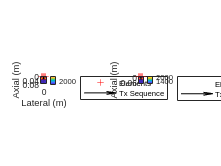

% Show the transducer's impulse response
% figure; plot(xdc.impulse, '.-'); title('Element Impulse Response');

% Show the transmit signal - a single point means it's a delta function
% figure; plot(seq.pulse, '.-'); title('Transmit signal');
%  Plot configuration of the simulation

figure; hold on; title('Geometry');
switch "both"
    case 'sound-speed', h = imagesc(med2, tscan, 'c'         ); colorbar; % show the sound speed 
    case 'density',     h = imagesc(med2, tscan, 'rho'       ); colorbar; % show the density
    case 'both',        h = imagesc(med2, tscan, ["c", "rho"]); % show both
    arrayfun(@colorbar, [h.Parent]); % same as "colorbar(h(1).Parent); colorbar(h(2).Parent); ..."
    hold([h.Parent], 'on');
end
for ax = [h.Parent]
plot(xdc, ax, 'r+', 'DisplayName', 'Elements'); % elements
if scan.nPix < 500,
    hps = plot(scan, ax, 'w.', 'MarkerSize', 0.5, 'DisplayName', 'Image'); % the imaging points
else
    warning("Not displaying (" + scan.nPix + ") imaging points.");
end
switch seq.type % show the transmit sequence
    case 'PW', plot(seq, ax, 3e-2, 'k.', 'DisplayName', 'Tx Sequence'); % scale the vectors for the plot
    otherwise, plot(seq, ax, 'k.', 'DisplayName', 'Tx Sequence'); % plot focal points, if they exist
end
hl = legend(ax, 'Location','bestoutside');
set(ax, 'YDir', 'reverse'); % set transducer at the top of the image
end

## Simulate the Response

% Construct an UltrasoundSystem object, combining all of these properties,
% adn setting the sampling frequency of the output data
us = UltrasoundSystem('xdc', xdc, 'sequence', seq, 'scan', scan, 'fs', 40e6);

Success recompiling bf.cu
Success recompiling interpd.cu
Success recompiling conv_cuda.cu
Success recompiling greens.cu
Building with 'gcc'.
MEX completed successfully.
Success recompiling msfm2d.c
Building with 'gcc'.
MEX completed successfully.
Success recompiling msfm3d.c



% Preferably, we use a parcluster to compute on - this makes it easy to
% send sims to the cluster
opts_clu = ["local", "Starling-GPU","Starling-CPU"];
switch opts_clu(2)
    case 'local', clu = parcluster('local'); % local computer - no setup required
        [clu.NumWorkers, clu.NumThreads] = deal(2, 4); % restrict to max 2 sims / 4 threads at a time
    case 'Starling-GPU',  clu = parcluster('Starling-GPU'); clu.SubmitArguments = clu.SubmitArguments + " --gpus=1" +" --mem=64GB"; % SLURM GPU partition
    case "Starling-CPU", clu = parcluster('Starling-CPU-bg'); % SLURM CPU background partition
end

% pick a folder for fullwave - it needs to write to disk
if clu.Profile == "local"
    fwsimdir = tempname(fullfile(pwd, 'sims')); % for fullwave, simulation in the working directory (current folder)
else
    user = strip(string(argn(2, @system, 'whoami'))); % get the username
    fwsimdir = tempname(fullfile('/data', user, 'fullwave', 'sims')); % make a temp directory for the simulation
end

% simulate the data
for i = numel(med):-1:1 % for each medium ...
    %switch "kWave"
    switch "kWave"
        case 'kWave', chd0(i) = kspaceFirstOrder(us, med, tscan, ...
                'CFL_max', 0.3, 'PML', [64 128], 'parcluster', clu, ... QUPS args
                'PlotSim', false ... KWave args - you can enter more here
                ); % giving a PML range selects an FFT friendly PML size

        case 'fullwave',
            conf = fullwaveConf(us, med(i), tscan, 'CFL_max', 0.3); % create a configuration structure
            job = us.fullwaveJob(conf, fwsimdir, clu); % create a job on the cluster
            submit(job); % launch - this may take a bit to copy over files
            wait(job); % wait for completion before reading back the data
        chd0(i) = us.readFullwaveSimEIK(fwsimdir, conf); % create the ChannelData
    end
end

     1     1

         256        3027          11

There are 3844401 points in the grid which is 14.665 megabytes per grid variable.


Error using rmfield
A field named 'BLIType' doesn't exist.

Error in UltrasoundSystem/kspaceFirstOrder (line 2148)
            kwave_args = rmfield(kwargs, nonkwfields); % forward all others

## display the channel data across the transmits

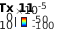

chd = mod2db(chd0); % == 20*log10(abs(x)) -> the power of the signl in decibels
figure; h = imagesc(chd, 1); colormap jet; colorbar; caxis(gather([-80 0] + (max(chd.data(chd.data < inf)))))
xlabel('Channel'); ylabel('Time (s)'); ylim([min(chd.time(:)), max(chd.time(:))]);
for m = 1:size(chd.data,3), if isvalid(h), h.CData(:) = chd.data(:,:,m); h.YData(:) = chd.time(:,:,min(m,size(chd.time,3))); drawnow limitrate; title(h.Parent, "Tx " + m); pause(1/10); end, end

## Create a B-mode Image(prev)


%{
% Precondition the datafalse
chd = chd0;
chd = singleT(chd); % use less data
chd.data = chd.data - mean(chd.data, 1, 'omitnan'); % remove DC
D = chd.getPassbandFilter(xdc.bw, 25); % get a 25-tap passband filter for the transducer bandwidth
chd = filter(chd, D); % apply passband filter for transducer bandwidth
if device, chd = gpuArray(chd); end % move data to GPU?
if isreal(chd), chd = hilbert(chd, 2^nextpow2(chd.T)); end % apply hilbert on real data

% Choose a beamforming method
apod = 1; % no apodization
%swith "DAS"
switch "Wavefield_Correlation"
    case "DAS"
        b =     bfDAS(us, chd, med(1).c0    , 'apod', apod, 'interp', 'cubic'); % use a vanilla delay-and-sum beamformer
    case "Eikonal"
        b = bfEikonal(us, chd, med(1), tscan, 'apod', apod, 'interp', 'cubic'); % use the eikonal equation for time delays
    case "DAS-direct"
        b =       DAS(us, chd, med(1).c0    , 'apod', apod, 'interp', 'cubic', 'device', device); % use a specialized delay-and-sum beamformer
    case "Wavefield_Correlation"
        % tscan.z should start at 0
        %assert(tscan.z(1) == 0, 'tscan.z should start at 0');
        %[b,img, p_tx_curr_allz_ifft,p_rx_curr_allz_ifft] = bfWavefieldCorrelation(us, chd, med, tscan,'plot', true); % use
        %clu = parcluster('Starling-GPU'); clu.SubmitArguments = clu.SubmitArguments + " --gpus=1";
        %b = bfWavefieldCorrelation_2(us, chd, med, tscan,'parcluster', clu, 'interp', 'cubic'); % use
        % s = SequenceRadial(); % hack 1
        us.sequence = Sequence('type', us.sequence.type, 'focus', us.sequence.focus, 'c0', us.sequence.c0, 'pulse', us.sequence.pulse); % downgrad because MATLAB sucks :(
        job = createJob(clu, 'AutoAttachFiles',true,'AutoAddClientPath', true);
        %job.AttachedFiles = [job.AttachedFiles, {'src/SequenceRadial.m'}]
        %job.addAttachedFiles("src/SequenceRadial.m");
        task = createTask(job, @bfWavefieldCorrelation, 1, {us, chd, med, tscan,'plot', true});
        % task = createTask(job, @wfc,1,{{us, gather(chd), med, tscan}});
        submit(job);
        [b,img, p_tx_curr_allz_ifft,p_rx_curr_allz_ifft] = job.fetchOutputs();
end

%}

nu=0;
switch "img_w_tdc"
    case "img_w_tdc"
        nu = 1;
    case "img_w/o_tdc"
        nu= 2;
    case "ptx"
        nu=3;
    case "rtx"
        nu=4
end

## Create a B-mode Image(new)

% Precondition the damedtafalse
%chd = chd0;
%chd = singleT(chd); % use less data
%chd.data = chd.data - mean(chd.data, 1, 'omitnan'); % remove DC
%D = chd.getPassbandFilter(xdc.bw, 25); % get a 25-tap passband filter for the transducer bandwidth
%chd = filter(chd, D); % apply passband filter for transducer bandwidth
%%if device, chd = gpuArray(chd); end % move data to GPU?
%if isreal(chd), chd = hilbert(chd, 2^nextpow2(chd.T)); end % apply hilbert on real data

%clu = parcluster('Starling-GPU'); clu.SubmitArguments = clu.SubmitArguments + " --gpus=1" +" --mem=32GB"; % SLURM GPU partition
% Choose a beamforming method
apod = 1; % no apodization
%swith "DAS"
switch "Wavefield_Correlation"
    case "DAS"
       % b =     DAS(us, chd, med.c0    , 'apod', apod, 'interp', 'cubic'); % use a vanilla delay-and-sum beamformer

          us.sequence = Sequence('type', us.sequence.type, 'focus', us.sequence.focus, 'c0', us.sequence.c0, 'pulse', us.sequence.pulse); % downgrad because MATLAB sucks :(
         job = createJob(clu, 'AutoAttachFiles', true);
             %,true , 'AutoAddClientPath', true);
        %job.AttachedFiles = [job.AttachedFiles, {'src/SequenceRadial.m'}]
        %job.addAttachedFiles("src/SequenceRadial.m");
         task = createTask(job, @DAS, 1, {us, chd, med.c0    , 'apod', apod, 'interp', 'cubic'}, 'CaptureDiary',true);
        % task = createTask(job, @wfc,1,{{us, gather(chd), med, tscan}});
         submit(job);
    case "Eikonal"
        b = bfEikonal(us, chd, med, tscan, 'apod', apod, 'interp', 'cubic'); % use the eikonal equation for time delays
    case "DAS-direct"
        b =       DAS(us, chd, med.c0    , 'apod', apod, 'interp', 'cubic', 'device', device); % use a specialized delay-and-sum beamformer
    case "Wavefield_Correlation"
        % tscan.z should start at 0
        %assert(tscan.z(1) == 0, 'tscan.z should start at 0');
        %[b,img, p_tx_curr_allz_ifft,p_rx_curr_allz_ifft] = bfWavefieldCorrelation(us, chd, med, tscan,'plot', true); % use
        %clu = parcluster('Starling-GPU'); clu.SubmitArguments = clu.SubmitArguments + " --gpus=1";
        %b = bfWavefieldCorrelation_2(us, chd, med, tscan,'parcluster', clu, 'interp', 'cubic'); % use
        % s = SequenceRadial(); % hack 1
        us.sequence = Sequence('type', us.sequence.type, 'focus', us.sequence.focus, 'c0', us.sequence.c0, 'pulse', us.sequence.pulse); % downgrad because MATLAB sucks :(
        job = createJob(clu, 'AutoAttachFiles',true);% , 'AutoAddClientPath', true);
        %job.AttachedFiles = [job.AttachedFiles, {'src/SequenceRadial.m'}]
        %job.addAttachedFiles("src/SequenceRadial.m");
        task = createTask(job, @bfWavefieldCorrelation, 1, {us, chd0, med, tscan,'plot',true, 'number',nu}, 'CaptureDiary',true);
        % task = createTask(job, @wfc,1,{{us, gather(chd), med, tscan}});
        submit(job);
        %[b,img, p_tx_curr_allz_ifft,p_rx_curr_allz_ifft] = job.fetchOutputs();

        %output = bfWavefieldCorrelation(us, chd, med, tscan, 'plot',false, 'number',nu);
end

%for das:
b = job.fetchOutputs();

b=b{1};

if nu ==1
    b = output;
elseif nu == 2
    img = ouput;
elseif nu ==3
    p_tx_curr_allz_ifft=output;
elseif nu ==4
    p_rx_curr_allz_ifft= output;
end

if nu ==1
    b = job.fetchOutputs();
    b=b{1};
elseif nu == 2
    img = job.fetchOutputs();
    img = img{1};
elseif nu ==3
    p_tx_curr_allz_ifft= job.fetchOutputs();
    p_tx_curr_allz_ifft = p_tx_curr_allz_ifft{1};
elseif nu ==4
    p_rx_curr_allz_ifft= job.fetchOutputs();
    p_rx_curr_allz_ifft = p_rx_curr_allz_ifft{1};

end

% show the image
im = mod2db(img); % convert to power in dB
figure; imagesc(scan, im(:,:,1), [-60, 0] + max(im(:))); % display with 80dB dynamic range
colormap gray; colorbar;

% show the image
b_im = mod2db(b); % convert to power in dB
figure; imagesc(scan, b_im(:,:,1), [-60, 0] + max(b_im(:))); % display with 80dB dynamic range
colormap gray; colorbar;

## transmit pressure


%p_tx_curr_allz_ifft_mag = abs(p_tx_curr_allz_ifft);
no_x_ifft = size(p_tx_curr_allz_ifft_mag,2)
no_z_ifft = size(p_tx_curr_allz_ifft_mag,1)

x=tscan.x;
z= tscan.z;
img_s = zeros(no_z_ifft, no_x_ifft);

%gfig = figure;
%%gax = gca;
%gim = imagesc(gax, 1000*x, 1000*z, db(abs(img_s)/max(abs(img_s(:)))), [-80, 0]);
%xlabel(gax, 'x Azimuthal Distance (mm)');
%ylabel(gax, 'z Axial Distance (mm)');
%title(gax, ['Image Reconstruction up to ', num2str(0/(1e6)), ' MHz']);
%zoom on;
%axis equal; axis xy; axis image;
%colormap gray; colorbar();
%xlim(gax, [-19.1,19.1]);
%set(gax, 'YDir', 'reverse');

p_tx_curr_allz_ifft_mag = abs(p_tx_curr_allz_ifft);
img_s = p_tx_curr_allz_ifft_mag;
no_time_ifft = size(p_tx_curr_allz_ifft_mag,3);

test = imagesc(img_s(:,:,1));

tscan.gif(img_s,'testinggif_t.gif',test);

## receive pressure

no_x_ifft_r = size(p_rx_curr_allz_ifft_mag,2)
no_z_ifft_r = size(p_rx_curr_allz_ifft_mag,1)

x=tscan.x;
z= tscan.z;
test_r = zeros(no_z_ifft_r, no_x_ifft_r);

p_rx_curr_allz_ifft_mag = abs(p_rx_curr_allz_ifft);
img_sr = p_rx_curr_allz_ifft_mag;
no_time_ifft_r = size(p_rx_curr_allz_ifft_mag,3);

test_r = imagesc(img_sr(:,:,1));
%grfig = figure;
%gaxr = gca;
%%gimr = imagesc(gaxr, 1000*x, 1000*z, db(abs(img_sr)/max(abs(img_sr(:)))), [-80, 0]);
%xlabel(gaxr, 'x Azimuthal Distance (mm)');
%ylabel(gaxr, 'z Axial Distance (mm)');
%title(gaxr, ['Image Reconstruction up to ', num2str(0/(1e6)), ' MHz']);
%zoom on;
%axis equal; axis xy; axis image;
%colormap gray; colorbar();
%xlim(gaxr, [-19.1,19.1]);
%set(gaxr, 'YDir', 'reverse');

tscan.gif(img_sr,'testinggif_r.gif',test_r);

